## Reading Data

fid = fopen("DATA.BIN", "rb", 'b');

if (fid ~= 0)
    disp("Open file succeed!");
else 
    disp("Open file failed!");
end

Open file succeed!



ftell(fid)

ans = 0

N_Sample = 8000000;
SAMPLE_POINT = N_Sample;
head = ftell(fid);

if (head ~= 0)
    fseek(fid, 0,'bof');
end
data_origin = fread(fid, N_Sample*4, 'uint8', 'b')

data_origin =    136
    32
     0
     0
   128
     8
     0
     0
     0
    64


% data_origin = dec2bin(data_origin)

fclose(fid);
data_origin(1:10);


% uint8 -> dec 
% data = dec2bin(s.UserData); 
data = dec2bin(data_origin)

data = 32000000×8 char 数组
    '10001000'
    '00100000'
    '00000000'
    '00000000'
    '10000000'
    '00001000'
    '00000000'
    '00000000'
    '00000000'
    '01000000'
    '00000110'
    '00000000'
    '00000100'
    '00000000'
    '00000000'
    '00000000'
    '10000100'
    '00100010'
    '00000000'
    '00000001'
    '00000000'
    '00000000'
    '10000000'
    '00000000'
    '01000010'
    '00100000'
    '00000110'
    '00000000'
    '01000000'
    '00000000'
    '00000000'
    '00000000'
    '10000000'
    '00100000'
    '00000010'
    '00100001'
    '10000000'
    '00000000'
    '00000000'
    '00000000'
    '00000000'
    '00000001'
    '00000111'
    '00000000'
    '00000000'
    '00100000'
    '00000000'
    '00000001'
    '11000011'
    '00000000'
    '00000011'
    '00000000'
    '00000000'
    '00000000'
    '00000000'
    '00000000'
    '10001000'
    '00000000'
    '00001000'
    '00100000'
    '00000000'
    '00000000'
    '00000000'
    '00000000'
    '11001010'


% d1 = data_origin(:, 25:32)
% d2 = data_origin(:, 17:24)
% d3 = data_origin(:, 9:16)
% d4 = data_origin(:, 1:8)

data_sorted = zeros(SAMPLE_POINT*4,8);
for i=1:SAMPLE_POINT*4
    switch mod(i,4)
        case 1
            data_sorted(i,:) = data(floor(i/4)*4+4, :);
        case 2
            data_sorted(i,:) = data(floor(i/4)*4+3, :);
        case 3
            data_sorted(i,:) = data(floor(i/4)*4+2, :);
        otherwise
            data_sorted(i,:) = data(i-3,:);
    end
end
data_sorted = char(data_sorted)

data_sorted = 32000000×8 char 数组
    '00000000'
    '00000000'
    '00100000'
    '10001000'
    '00000000'
    '00000000'
    '00001000'
    '10000000'
    '00000000'
    '00000110'
    '01000000'
    '00000000'
    '00000000'
    '00000000'
    '00000000'
    '00000100'
    '00000001'
    '00000000'
    '00100010'
    '10000100'
    '00000000'
    '10000000'
    '00000000'
    '00000000'
    '00000000'
    '00000110'
    '00100000'
    '01000010'
    '00000000'
    '00000000'
    '00000000'
    '01000000'
    '00100001'
    '00000010'
    '00100000'
    '10000000'
    '00000000'
    '00000000'
    '00000000'
    '10000000'
    '00000000'
    '00000111'
    '00000001'
    '00000000'
    '00000001'
    '00000000'
    '00100000'
    '00000000'
    '00000000'
    '00000011'
    '00000000'
    '11000011'
    '00000000'
    '00000000'
    '00000000'
    '00000000'
    '00100000'
    '00001000'
    '00000000'
    '10001000'
    '00000000'
    '00000000'
    '00000000'
    '00000000'
    '00

data_tag = data_sorted(:,1:2);

if (sum(mod(find(data_tag=='11'), 4)) > 0 )
    disp("Data Missing!");
    index = find(data_tag == '11');
    index_mod = mod(index, 4);
    fprintf("Missing data occured at %d sampled point;\n",find(index_mod ~= 0, 5))
    
else
    disp("Data Right!");
end

Data Missing!


Missing data occured at 4 sampled point;
Missing data occured at 10 sampled point;
Missing data occured at 13 sampled point;
Missing data occured at 47 sampled point;
Missing data occured at 49 sampled point;


data_sign = str2num(data_sorted(:,3));
data_value = data_sorted(:,4:end);

data_sign(data_sign==1) = -1;
data_sign(data_sign==0) = 1;
data_value = bin2dec(data_value) .* data_sign

data_value =      0
     0
     0
     8
     0
     0
     8
     0
     0
     6


data_N4 = reshape(data_value, [4, SAMPLE_POINT])';
clear data_orgin data data_value data_sign data_sorted

data_N4 = data_N4(10001:end, :);

## Calibration

% ~~~~~~~~~~~~~~~ test environment ~~~~~~~~~~~~~~~
% clk_50M = 50E6;
% clk_adc = clk_50M / 5_000 ;
% fs = clk_adc / 50;

Vref = 1.8;
N_SUB = 5;
LSB_SUB = Vref / 2^N_SUB;

% ~~~~~~~~~~~~~~~ calculate gain ~~~~~~~~~~~~~~~
% gain = zeros(1,N_Sample);
% for i = 1:N_Sample
%     if (mod(i, 2) == 0)
%         gain_temp = Newton_Calib(-1*data_N4(i,2:end), 10);
%         gain(i) = gain_temp(10);
%     else 
%         gain_temp = Newton_Calib(data_N4(i,2:end), 10);
%         gain(i) = gain_temp(10);
%     end
% end

% Newton_Calib(data_N4(1,2:end) - data_N4(2,2:end), 10)
gain = deltaGain(data_N4(:,2:end), 10);

% gain = abs(gain);
% GAIN = mean(gain);
% % ~~~~~~~~~~~~~~~ display result ~~~~~~~~~~~~~~~
% figure
% hold on;
% plot(gain);
% % plot(gain_plus);
% plot(ones([1,N_Sample/2])*GAIN)
% % plot(ones([1,N_Sample/2])*GAIN_PLUS)
% hold off;
% xlim([0, N_Sample/2]);
% 
% legend(["LSB calibraion", "-LSB average"], ...
%     'Location', 'northeast')
% xlabel("Sample Point");
% ylabel("Gain with Calibration");
% 
% 


% ~~~~~~~~~~~~~~~ display result ~~~~~~~~~~~~~~~
gain_min = abs(gain(1:2:end));
gain_plus = abs(gain(2:2:end));

GAIN_MIN = mean(gain_min)

GAIN_MIN = 15.1652

GAIN_PLUS = mean(gain_plus)

GAIN_PLUS = 15.1652

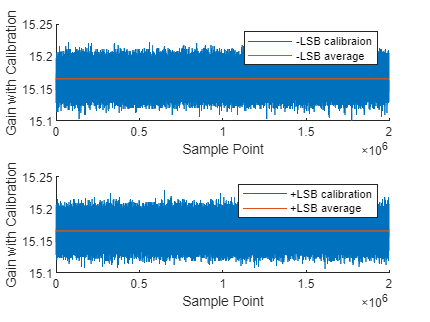



figure
subplot(2,1,1)
hold on;
plot(gain_min);
plot(ones([1,N_Sample/4])*GAIN_MIN)
hold off;
xlim([0, N_Sample/4]);

legend(["-LSB calibraion", ...
    "-LSB average"], ...
    'Location', 'northeast')
xlabel("Sample Point");
ylabel("Gain with Calibration");

subplot(2,1,2)
hold on;
plot(gain_plus);
plot(ones([1,N_Sample/4])*GAIN_PLUS)
hold off;
xlim([0, N_Sample/4]);

legend(["+LSB calibration",...
     "+LSB average"], ...
    'Location', 'northeast')
xlabel("Sample Point");
ylabel("Gain with Calibration");